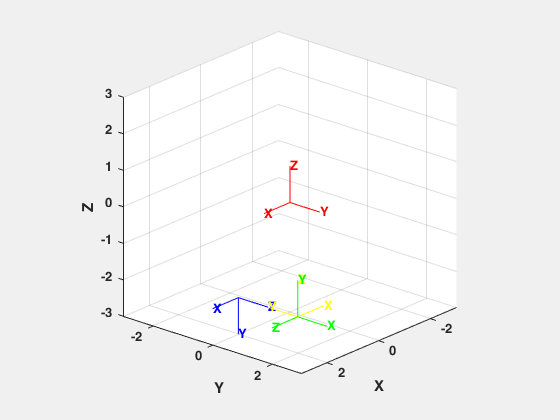

A = serialport("COM9",115200);
configureTerminator(A,"CR/LF");
flush(A);

% Variables
button = zeros(1,4); % Button Values
encval = zeros(1,12); % Encoder Values



% Main Loop
while(true)
    data = readline(A);
    if (data == "Start") 
        break 
    end
end

data = readline(A);
newdata = split(data,',');
receive = zeros(1,16);
for i = 1:16
    receive(i) = double(newdata(i));
end
for i = 1:16
    if (i<5)
        button(i) = receive(i);
    else 
        encval(i-4) = AngleConvert(receive(i),"degree");
    end
end
while(true)
    % Connecting the link
    f = figure;
    plotvol([-3 3 -3 3 -3 3]);
    view([131.01 21.85])
    
    TrWorld = eye(4);
    trplot(TrWorld,'framelabel', 'World', 'color', 'r');
    TrW4 = DHLink(-2,0,2,-90);
    trplot(TrW4,'framelabel', 'W4', 'color', 'b');
    Tr45 = TrW4*DHLink(2,180,0,-90);
    trplot(Tr45,'framelabel', '45', 'color', 'y');
    Tr56 = Tr45*DHLink(0,-90,0,90);
    trplot(Tr56,'framelabel', '56', 'color', 'g');
    pause(1);

    close(f)
end
clear

